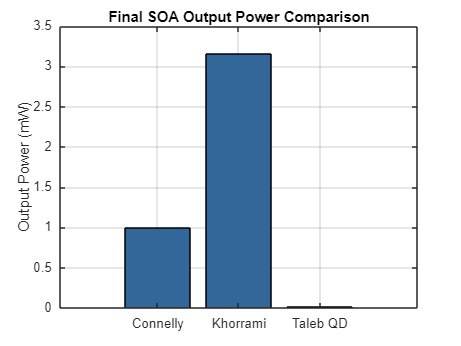

% %% Comparison of 3 Semiconductor Optical Amplifier (SOA) Models
% % Michael Connelly Model | Yaser Khorrami Model | Hussein Taleb QD-SOA Model

clc; clear; close all;

%% Common Parameters (for Khorrami & Taleb)
input_power_dBm = -20;
input_power_common = 10^((input_power_dBm - 30)/10);  % W, =10^(–50/10)=1e–5 W

%% 1. Michael Connelly Model (local variables)
% — these overrides stay local to Connelly and don’t touch the others —
q = 1.602e-19; 
h = 6.626e-34; 
c = 3e8;
Gamma = 0.3;
g0 = 5e3;               % 1/m
N0 = 1e24;              % 1/m³
tau_c = 500e-12;        % s
A_eff = 1e-12;          % m²
L_con = 500e-6;         % m
V_con = A_eff * L_con;  % m³

bias_current_con = 10e-3;   % A
input_power_con  = 1e-3;    % W (1 mW)

% Carrier generation
R = bias_current_con / (q * V_con);
N = R * tau_c;
delta_N = max(0, N - N0);
delta_N = min(delta_N, 0.25e24);  % cap surplus

% Clamped gain
gain_exponent = Gamma * g0 * delta_N * L_con;
gain_exponent = min(gain_exponent, 5);
gain_linear = exp(gain_exponent);

P_out_Connelly = input_power_con * gain_linear;    % W

%% 2. Khorrami Model (uses input_power_common)
G0_dB = 25;
G0 = 10^(G0_dB/10);
P_sat = 5e-3;                                      % W
G_Khorrami = G0 / (1 + input_power_common / P_sat);
P_out_Khorrami = input_power_common * G_Khorrami;  % W

%% 3. Hussein Taleb QD Model (uses input_power_common)
t = linspace(0,1e-9,1000);
dt = t(2)-t(1);
N_WL = zeros(size(t));
N_ES = zeros(size(t));
N_GS = zeros(size(t));

tau_wl = 0.5e-12; 
tau_es = 1e-12; 
tau_gs = 300e-12;
Pump = 5e23;      % Pump rate
for i = 2:length(t)
    N_WL(i) = N_WL(i-1) + dt*(Pump - N_WL(i-1)/tau_wl);
    N_ES(i) = N_ES(i-1) + dt*(N_WL(i-1)/tau_wl - N_ES(i-1)/tau_es);
    N_GS(i) = N_GS(i-1) + dt*(N_ES(i-1)/tau_es - N_GS(i-1)/tau_gs);
end

gain_scaling = 1e-24;
G_Taleb = exp( min( tanh(gain_scaling * N_GS(end)) * 25, 30 ) );
P_out_Taleb = input_power_common * G_Taleb;  % W

%% Plot Results
figure;
bar([P_out_Connelly, P_out_Khorrami, P_out_Taleb]*1e3, 'FaceColor',[0.2 0.4 0.6]);
ylabel('Output Power (mW)');
set(gca,'XTickLabel',{'Connelly','Khorrami','Taleb QD'});
title('Final SOA Output Power Comparison');
grid on;


%% Display in command window
fprintf('   --- Output Power Comparison ---\n');

   --- Output Power Comparison ---


fprintf('Connelly Model Output Power: %.3f mW\n', P_out_Connelly*1e3);

Connelly Model Output Power: 1.000 mW


fprintf('Khorrami Model Output Power:  %.3f mW\n', P_out_Khorrami*1e3);

Khorrami Model Output Power:  3.156 mW


fprintf('Taleb QD Model Output Power:  %.3f mW\n', P_out_Taleb*1e3);

Taleb QD Model Output Power:  0.010 mW
